Generation: 1, Fitness Standard Deviation: 664.232780
Generation: 2, Fitness Standard Deviation: 333.403200
Generation: 3, Fitness Standard Deviation: 377.980324
Generation: 4, Fitness Standard Deviation: 325.790257
Generation: 5, Fitness Standard Deviation: 346.343016
Generation: 6, Fitness Standard Deviation: 312.211275
Generation: 7, Fitness Standard Deviation: 322.520787
Generation: 8, Fitness Standard Deviation: 329.643441
Generation: 9, Fitness Standard Deviation: 360.837760
Generation: 10, Fitness Standard Deviation: 342.666460
Generation: 11, Fitness Standard Deviation: 297.073753
Generation: 12, Fitness Standard Deviation: 384.683559
Generation: 13, Fitness Standard Deviation: 390.858324
Generation: 14, Fitness Standard Deviation: 342.612921
Generation: 15, Fitness Standard Deviation: 398.010228
Generation: 16, Fitness Standard Deviation: 336.778338
Generation: 17, Fitness Standard Deviation: 351.243024


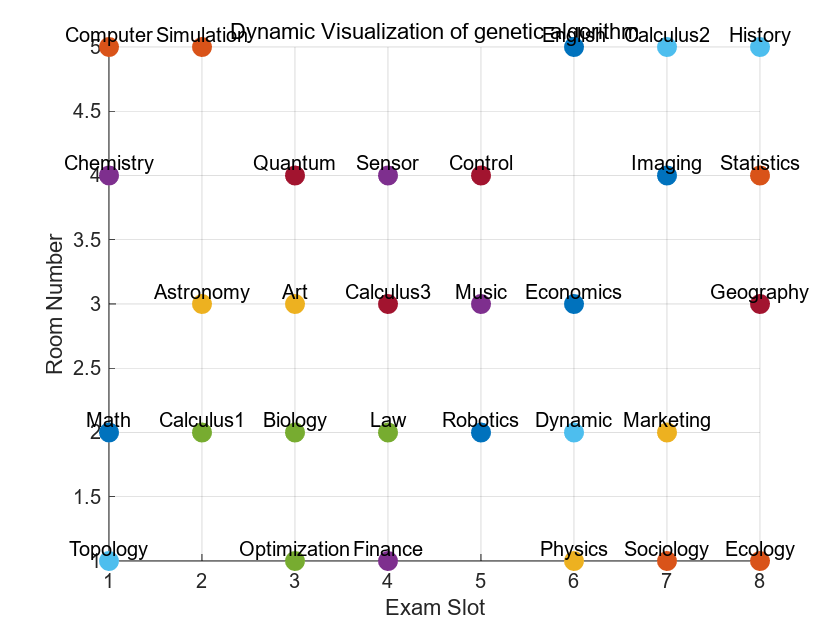

final_schedule = schedule_optimization();

function final_schedule = schedule_optimization()
    tic;

    % variable
    num_exams = 30; % total number of examinations
    num_rooms = 5; % total available rooms
    num_slots = 8; % total available exam periods
    room_capacity = [30, 25, 40, 35, 20]; 
    exam_students = [25, 20, 35, 30, 15, 10, 30, 20, 30, 25,29,15,12,26,13,20,15,23,25, 20, 35, 30, 15, 10, 20,25,28,34,15,30]; % Number of students per exam
    exam_names = {'Math', 'Simulation','Astronomy','Sensor','Optimization','Dynamic','Control','Imaging','Statistics','Physics', 'Chemistry', 'Biology', 'History', 'Geography', 'English', 'Computer', 'Art', 'Music', 'Calculus1','Calculus2','Calculus3','Economics','Sociology','Marketing','Finance','Law','Topology','Quantum','Robotics','Ecology'};

    % Student course selection matrix
    % Student course selection matrix
    total_students = 150;
    student_courses = zeros(total_students, num_exams);
    % Adjust the matrix to ensure the number of students per exam matches exam_students
    for exam = 1:num_exams
        % Randomly select students for the exam
        selected_students = randperm(total_students, exam_students(exam));
        student_courses(selected_students, exam) = 1;
    end
    % 1. create_initial_schedule
    initial_schedule = create_initial_schedule(num_exams, num_rooms, num_slots, exam_students, room_capacity);

    % 2. Using Genetic Algorithm to give a better starting point for the following Annealing Algorithm
  
    [optimized_schedule, ga_fitness_history, ga_solutions_history] = B_genetic_algorithm(initial_schedule, num_exams, num_rooms, num_slots, room_capacity, exam_students, student_courses,exam_names);

   
 
    % 3.Visualizing the optimized schedule of the genetic algorithm
    Z_visualize_final_schedule(optimized_schedule, exam_names, num_slots, num_rooms, room_capacity, exam_students);

    % 4. Generate and save exam schedules for all students
    Z_save_all_student_schedules(optimized_schedule, exam_names, student_courses, 'AllStudentSchedules_GA.csv');

    %======================================================================================================================================================
    
  
    % Genetic algorithm fitness value change chart
    figure;
    plot(1:length(ga_fitness_history), ga_fitness_history, 'b-', 'LineWidth', 2);
    xlabel('iteration');
    ylabel('fitness value');
    title('Genetic Algorithm Fitness');
    grid on;

    

    elapsed_time = toc;
    fprintf('Total time elapsed: %.2f seconds.\n', elapsed_time);

    final_schedule = optimized_schedule;

end


%==============================================================================================================================
% Reference:
% [1]https://taytzehao.medium.com/classroom-scheduling-using-heuristics-and-genetic-algorithm-b7279ecdd74c
% [2]Genetic Algorithm For University Course Timetabling Problem Genetic Algorithm For University Course Timetabling Problem 
% [3]Genetic Algorithm For Solving University Course Timetabling Problem Using Dynamic Chromosomes
% [4]https://blog.csdn.net/zbw237798856/article/details/134159792?utm_medium=distribute.pc_relevant.none-task-blog-2~default~baidujs_baidulandingword~default-0-134159792-blog-47809595.235^v43^pc_blog_bottom_relevance_base5&spm=1001.2101.3001.4242.1&utm_relevant_index=3
% [5]ChatGPT